# Pulseq-CEST

The following live script demonstrates how to generate an pulseq-file for an APT-weighted CEST experiment with Pulseq-CEST.

## Installation

The Pulseq-CEST MATLAB Code can be cloned from git and is set up using the Installation script

% if you do not have git installed you can use the commented lines to unzip
% the code directly from GitHub:
% unzip("https://github.com/kherz/pulseq-cest/archive/master.zip");
% movefile('pulseq-cest-master', 'pulseq-cest');
system('git clone https://github.com/kherz/pulseq-cest');

Cloning into 'pulseq-cest'...


cd pulseq-cest;
Install_pulseq_cest;

git found, cloning external libraries...
Running git in D:\scripts\pulseqSBB_Sim\mrpub\pulseq-cest
Installing pulseq-cest-library...
...done!
Installing yamlmatlab...
...done!
Adding files to path.
Installation finished!


cd ..


The pulseq-cest-library repository was cloned during the installation: 

dir('pulseq*')


pulseq-cest          pulseq-cest-library  



The *pulseq-cest* folder contains the core funtionality and all the functions to simulate CEST protocols, whereas the *pulseq-cest-library *is a database for different protocols.

For this tutorial, we have a detailled look into the generation of an APT-weighted protocol from the *pulseq-cest-library.*

cd pulseq-cest-library\seq-library\APTw_3T_001_2uT_36SincGauss_DC90_2s_braintumor\

Each protol in the library comes with a MATLAB and python script to generate the pulseq-file, as well as a short description and of course the pulseq-file itself. Let's have a detailled look into the MATLAB generation file.

The *seq_def* struct contains everything that gets later stored as a definition in the pulseq-file. This can contain anything you would need later for post-processing etc.

seqid = 'APTw_3T_001_2uT_36SincGauss_DC90_2s_braintumor';
seq_defs.n_pulses      = 36              ; % number of pulses
seq_defs.tp            = 50e-3           ; % pulse duration [s]
seq_defs.td            = 5e-3            ; % interpulse delay [s]
seq_defs.Trec          = 3.5             ; % recovery time [s]
seq_defs.Trec_M0       = 3.5             ; % recovery time before M0 [s]
seq_defs.M0_offset     = -1560           ; % m0 offset [ppm]
seq_defs.DCsat         = (seq_defs.tp)/(seq_defs.tp+seq_defs.td); % duty cycle
seq_defs.offsets_ppm   = [seq_defs.M0_offset -4:0.25:4]; % offset vector [ppm]
seq_defs.num_meas      = numel(seq_defs.offsets_ppm)   ; % number of repetition
seq_defs.Tsat          = seq_defs.n_pulses*(seq_defs.tp+seq_defs.td) - ...
                         seq_defs.td ;  % saturation time [s]
seq_defs.B0            = 3               ; % B0 [T]
seq_defs.seq_id_string = seqid           ; % unique seq id


You can find them in the existing pulseq-file in the [DEFINITIONS]:

fid = fopen('APTw_3T_001_2uT_36SincGauss_DC90_2s_braintumor.seq');
while ~strcmp(fgetl(fid), '[DEFINITIONS]')
    continue;
end
def = '[DEFINITIONS]';
while ~isempty(def)
    disp(def);
    def = fgetl(fid);
end

[DEFINITIONS]
B0 3 
B1cwpe 1.9962 
DCsat 0.909091 
M0_offset -1560 
Trec 3.5 
Trec_M0 3.5 
Tsat 1.975 
n_pulses 36 
num_meas 34 
offsets_ppm -1560 -4 -3.75 -3.5 -3.25 -3 -2.75 -2.5 -2.25 -2 -1.75 -1.5 -1.25 -1 -0.75 -0.5 -0.25 0 0.25 0.5 0.75 1 1.25 1.5 1.75 2 2.25 2.5 2.75 3 3.25 3.5 3.75 4 
seq_id_string APTw_3T_001_2uT_36SincGauss_DC90_2s_braintumor 
td 0.005 
tp 0.05 


fclose(fid);

After the definitions, we prepare the variables we need to fill the pulseq-file.

Pulseq takes care of scanner limits, such as gradient slew rates, rf times, etc. We provide a function to set some low-demand limits.

lims = Get_scanner_limits()

lims = struct with fields:
           maxGrad: 1703040
           maxSlew: 5.5349e+09
          riseTime: []
        rfDeadTime: 1.0000e-04
    rfRingdownTime: 3.0000e-05
       adcDeadTime: 0
      rfRasterTime: 1.0000e-06
    gradRasterTime: 1.0000e-05
             gamma: 42576000


In the next step we create the saturation pulses. Pulseq comes with some basic pulse shahes that can be further adapted with additional parameters. For this example we use a Sinc pulse with an adjusted time-bandwidth product and apodization.

B1pa          = 1.78;                  % mean sat pulse b1 [uT]
gyroRatio_hz  = 42.5764;               % for H [Hz/uT]
gyroRatio_rad = gyroRatio_hz*2*pi;     % [rad/uT]
fa_sat        = B1pa*gyroRatio_rad*seq_defs.tp; % flip angle of sat pulse
satPulse      = mr.makeSincPulse(fa_sat, 'Duration', seq_defs.tp, 'system', lims,'timeBwProduct', 2,'apodization', 0.15);

It is also possible to calculate the different power equivalents from the saturation pulse and the duty cycle of the entire preparation. We use that to store the B1 continous wave power equivalent in the pulseq-file:

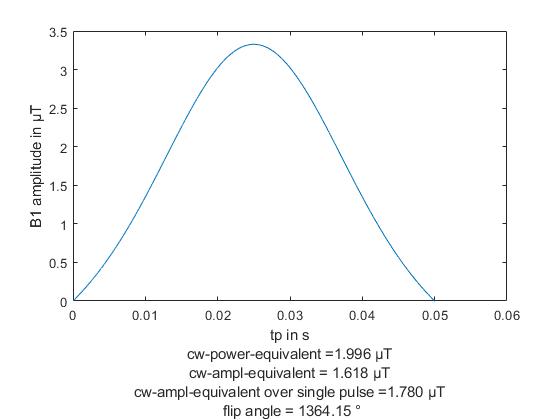

[B1cwpe,B1cwae,B1cwae_pure,alpha]= calc_power_equivalents(satPulse,seq_defs.tp,seq_defs.td,1,gyroRatio_hz);

seq_defs.B1cwpe = B1cwpe;

As a last step we generate spoiler gradients and the pseudo-ADC event at which the signal is sampled in the simulation, or the readout sequence is called on the scanner.

% spoilers
spoilRiseTime = 1e-3;
spoilDuration = 4500e-6 + spoilRiseTime; % [s]
[gxSpoil, gySpoil, gzSpoil] = Create_spoiler_gradients(lims, spoilDuration, spoilRiseTime);

% pseudo adc, not played out
pseudoADC = mr.makeAdc(1,'Duration', 1e-3);

Now we have all the objects we need and can fill the pulseq-file by looping through the offsets we want to simulate / measure.

% init sequence
seq = mr.Sequence();

% pulseq uses offsets in Hz
offsets_Hz = seq_defs.offsets_ppm*gyroRatio_hz*seq_defs.B0;

% loop through offsets
for currentOffset = offsets_Hz
    % if the current offset is an M0 scan we use the M0 recovery time
    if currentOffset == seq_defs.M0_offset*gyroRatio_hz*seq_defs.B0
        if seq_defs.Trec_M0 > 0
            seq.addBlock(mr.makeDelay(seq_defs.Trec_M0));
        end
    else % if no M0 scan use Trec
        if seq_defs.Trec > 0
            seq.addBlock(mr.makeDelay(seq_defs.Trec)); % recovery time
        end
    end
    % set frequency offset of the pulse
    satPulse.freqOffset = currentOffset;
    
    % take care of the accumulated phase during the saturation
    accumPhase=0;
    
    % loop through pulses
    for np = 1:seq_defs.n_pulses
        % set accumulated pahse from previous rf pulse
        satPulse.phaseOffset = mod(accumPhase,2*pi); 
        % add satURATION PULSE pulse
        seq.addBlock(satPulse) 
        % calculate the phase for the next rf pulse
        accumPhase = mod(accumPhase + currentOffset*2*pi*(numel(find(abs(satPulse.signal)>0))*1e-6),2*pi);
        % delay between pulses
        if np < seq_defs.n_pulses
            seq.addBlock(mr.makeDelay(seq_defs.td)); % add delay
        end
    end
    % add the spoiling gradients
    seq.addBlock(gxSpoil,gySpoil,gzSpoil);
    % add the readout trigger event
    seq.addBlock(pseudoADC); 
end

As a last step we add the definitions to the pulseq-file that we defined in the beginning and write the file.

%% set definitions
def_fields = fieldnames(seq_defs);
for n_id = 1:numel(def_fields)
    seq.setDefinition(def_fields{n_id}, seq_defs.(def_fields{n_id}));
end
% write the pulseq-file
seq_filename = 'Demo.seq';
seq.write(seq_filename);

Lets have a look at the first saturation phase: 

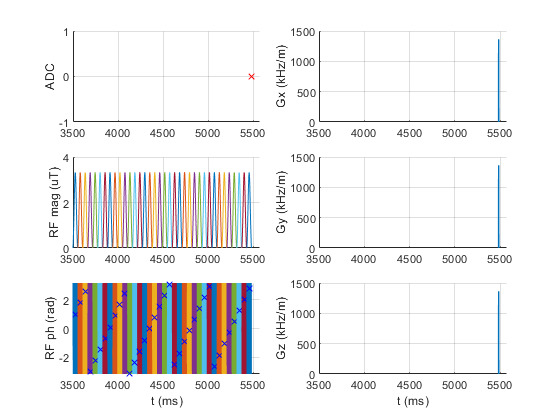

t_start = seq_defs.Trec_M0;                       % starting time for plot in s
t_stop  = seq_defs.Trec_M0 + seq_defs.Tsat + 0.1; % end time for plot in s
% plot first saturation phase after M0 recovery
seq.plot('TimeRange',[t_start, t_stop],'timeDisp','ms','rfDisp','uT','gammaHz',42.5764);

This file could now be used at the scanner with the Pulseq-CEST hybrid sequence. But it is of course also possible to use it in our simulation. For this purpose we provide simulation parameters in the *pulseq-cest-library*. Lets have a look at the content of the simulation parameters file for gray matter at 3T.

sim_parameters = yaml.ReadYaml('../../sim-library/GM_3T_001_bmsim.yaml')

sim_parameters = struct with fields:
           water_pool: [1×1 struct]
              mt_pool: [1×1 struct]
            cest_pool: [1×1 struct]
                   b0: 3
                gamma: 267.5153
             b0_inhom: 0
               rel_b1: 1
              verbose: 0
       reset_init_mag: 1
                scale: 0.5000
    max_pulse_samples: 300


sim_parameters.water_pool

ans = struct with fields:
     f: 1
    r1: '1 / 1.3'
    r2: '1 / 75e-3'


sim_parameters.mt_pool

ans = struct with fields:
            f: '5.5 / 111'
           r1: '1 / 1.3'
           r2: '1 / 9e-6'
            k: 40
           dw: 0
    lineshape: 'SuperLorentzian'


sim_parameters.cest_pool

ans = struct with fields:
          amide: [1×1 struct]
    guanidine_1: [1×1 struct]
        amine_1: [1×1 struct]
          NOE_1: [1×1 struct]


sim_parameters.cest_pool.amide

ans = struct with fields:
     f: '72e-3 / 111'
    r1: '1 / 1.3'
    r2: '1 / 100e-3'
     k: 30
    dw: 3.5000


As you can see, all relevant parameters for simulation are stored in the human-readbale yaml-file. We can use this in combination with our pulseq-file directly in the simulation.

M_z = Run_pulseq_cest_Simulation(seq_filename,'../../sim-library/GM_3T_001_bmsim.yaml');

Simulating .seq file ... 
Simulating .seq file took 11.986 s


The simulation returns the Z-magnetization which we can now plot together with the MTRasym.

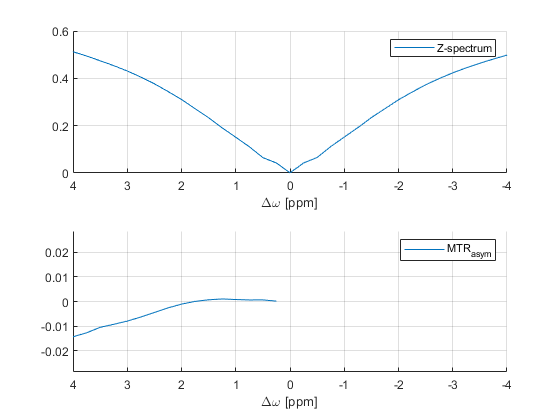

Plot_pulseq_cest_Simulation(M_z, seq_defs.offsets_ppm, seq_defs.M0_offset);